# Interpolation of Complex Values

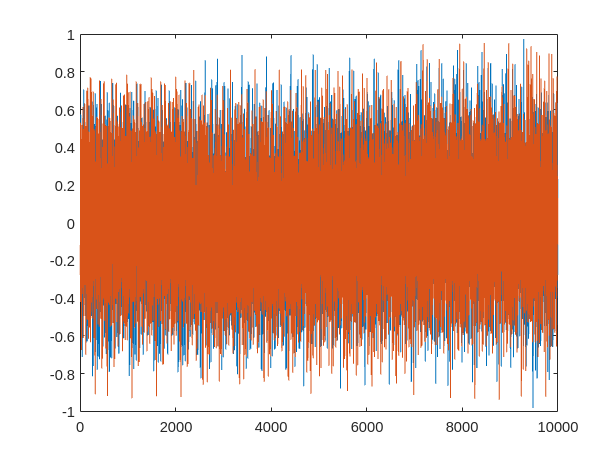

load("/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/heltf160.mat")
data = read_complex_binary('/mnt/tmp/usrp_160_breathe2.dat');
i = 4;
symbollen_table = [288, 576, 1152, 2304];
gilen_table = [32, 64, 128, 256];
symbollen = symbollen_table(i);
gilen = gilen_table(i);
data1 = [data; zeros(symbollen - mod(length(data), symbollen), 1)];
data1 = reshape(data1, [symbollen, length(data1) / symbollen]);
cfr_all=fftshift(fft(data1(cfg.gilen+1:end, :)));
cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
[I1,pos1] = max(cir);

N = length(cfr_all);

figure
plot(real(data(1:10000)))
hold on
plot(imag(data(1:10000)))
hold on

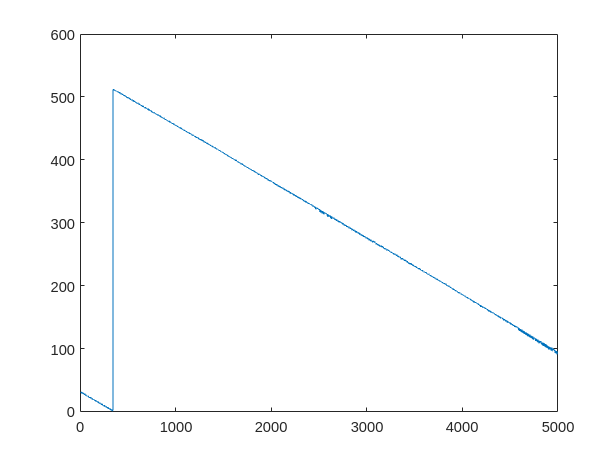


figure
plot(pos1(1:5000))

hold on
% 
% figure
% corr_result = conv(data, bb(1,:));
% corr_result = [corr_result; zeros(symbollen - mod(length(corr_result), symbollen), 1)]; 
% corr_result2 = reshape(corr_result, [symbollen, length(corr_result) / symbollen]);
% plot(abs(corr_result2))
% hold on
% figure
% imagesc(abs(cir))
% ylim([511 517])
% hold on% xlim([1 500])


cfr_all=fftshift(fft(data1(cfg.gilen+1:end,:)));
cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution

figure
imagesc(abs(cir))
ylim([511 517])
hold on% xlim([1 500])
% for i = 1:1000
% cir(:,i) = circshift(cir(:,i),round(i * 0.09));
% end
% figure
% imagesc(abs(cir))
% ylim([511 517])
% hold on% xlim([1 500])/11-
theta = angle(cir(:,:));
theta_diff = [zeros(2048,1),diff(theta, 1, 2)];
theta_unwrap = unwrap(theta, 0, 2);
figure
for i = 2040:2048
plot(theta_unwrap(i,:))
hold on
end
legend()


pos1(end-2:end) = pos1(end-3);
start = pos1+256 + (0:length(pos1) - 1) * 2304;
finish = start + 2047;

data_useful = zeros(2048, length(data1)-5);

for i = 1:1:length(data_useful)-5
data_useful(:,i) = data(start(i):finish(i));
end

cfr_all=fftshift(fft(data_useful(1:end,:)));
cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
[~,pos] = max(cir);

figure
plot(pos(1:5000))
hold on

figure
imagesc(abs(cir))
ylim([511 517])
hold on
figure
imagesc(abs(diff(cir, 1, 2)))
hold on
figure
plot(abs(cir(512,:)))
hold on
% plot(abs(MovingAverageFilter(cir(512,:),100)))   
% hold on
figure
plot(abs(cir(513,:)))
hold on
% plot(3*abs(lowpass(cir(513,:),150,200e6)))   
% hold on
figure
plot(abs(cir(514,:)))
hold on
% plot(3*abs(lowpass(cir(514,:),150,200e6)))   
% hold on
figure
plot(abs(cir(515,:)))
hold on

figure
plot(abs(cir(516,:)))
hold on

figure
plot(abs(cir(517,:)))
hold on

% cfr_all=fftshift(fft(data1(257:end,:)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
theta = angle(cir(:,:));
theta_diff = [zeros(2048,1),diff(theta, 1, 2)];
theta_unwrap = unwrap(theta, 0, 2);
% figure
% for i = 1:2048
% plot(theta_unwrap(i,:));
% hold on
% end

slope = zeros(2048,1);
for i = 1:2048
mdl = fitlm(1:length(theta_unwrap),theta_unwrap(i,:));
slope(i,:) = mdl.Coefficients.Estimate(2);  % the coefficients
end
% figure
% plot(slope)
% hold on
slope_dif = slope - slope(1024);

figure
plot(slope_dif)
hold on

% SFO compensation
t = 1:N-5;
SFO_theta = t .* slope_dif;
cir_sfo = cir(:,:) .* exp(-1j * SFO_theta);
theta = angle(cir_sfo(:,:));
theta_unwrap_sfo = unwrap(theta, 0, 2);
% figure
% for i = 1:2048
% plot(theta_unwrap_sfo(i,:));
% hold on
% end

% CFO compensation
slope2 = zeros(2048,1);
for i = 1:2048
mdl = fitlm(1:length(theta_unwrap_sfo),theta_unwrap_sfo(i,:));
slope2(i,:) = mdl.Coefficients.Estimate(2);  % the coefficients
end
max(slope2)-min(slope2)
mean(slope2)
CFO_theta = theta(513,:);
% t = 1:N-5;
% CFO_theta = t .* mean(slope2);
cir_cfo = cir_sfo(:,:) .* exp(-1j  * CFO_theta);
theta_cfo = angle(cir_cfo(:,:));
theta_unwrap_cfo = unwrap(theta_cfo, 0, 2);
% figure
% for i = 1:2048
% plot(theta_unwrap_cfo(i,:));
% hold on
% end

[~,pos] = max(cir_sfo);
figure
imagesc(abs(cir_sfo))
ylim([511 517])
hold on
title('After SFO compensation')


% cir_cfo=ifft(fftshift(cfr_cfo.*conj(cfg.userltf(1,:)'))); %convolution
[~,pos] = max(cir_sfo);
figure
imagesc(abs(cir))
ylim([511 517])
hold on
title('After CFO compensation')

% 
% cir_dif = diff(cir, 1, 2);
% figure
% imagesc(abs(cir_dif))
% ylim([511 517])
% hold on

% % Calculate the phases of every Rx pilot tone% Calculate the phases of every Rx pilot tone
% pilot_phases = unwrap(angle(fftshift(cfr_all(513,:))), [], 1);
% 
% % Calculate slope of pilot tone phases vs frequency in each OFDM symbol
% % pilot_diff = diff(pilot_phases);
% pilot_slope_mat = mean(diff(pilot_phases));
% 
% % Calculate the SFO correction phases for each OFDM symbol
% pilot_phase_sfo_corr = fftshift((-1024:1023).' * pilot_slope_mat, 1);
% pilot_phase_corr = exp(-1i*(pilot_phase_sfo_corr));
% 
% % Apply the pilot phase correction per symbol
% cfr_all = cfr_all .* pilot_phase_corr;
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% 
% figure
% plot(pos1)
% hold on
% 
% figure
% imagesc(abs(cir))
% ylim([511 517])
% hold on
% mdl_1 = fitlm(1:342,pos1(1:342))
% mdf_2 = fitlm(1:5700, pos1(343:6042))
% mdl_3 = fitlm(1:871, pos1(6043:end))
% v = 0:-1:-30;
% del = repelem(v,11);
% del(:,1:7) = []
% pos2 = 31 + del;
% 
% M = movmean(pos1(1:340),11);

% pos2 = round(30.955 - 0.08856 * (1:340));
% pos3 = round(514 - 0.09 * (1:5700));
% pos4 = round(512.5 - 0.09 * (1:871));
% 
% n = length(data1)
% pos_n = round(31 - 0.09 * (1:n-3));
% 
% start = pos_n+256 + (0:n-4) * 2304;
% finish = start + 2047;
% 
% data_useful = zeros(2048, n-3);
% 
% for i = 1:1:n-3
% data_useful(:,i) = data(start(i):finish(i));
% end
% 
% cfr_all=fftshift(fft(data_useful(1:end,:)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% [~,pos] = max(cir);
% figure
% imagesc(abs(cir(511:516,:)))
% % xlim([1 500])
% hold on



% % 
% % figure
% % plot(abs(cir(1:2048*4340)));   
% % hold on
% 
% data1 = [data; zeros(symbollen - mod(length(data), symbollen), 1)];
% data1 = reshape(data1, [symbollen, length(data1) / symbollen]);
% 
% num = 2048;
% pos_diff = -621;
% 
% data_use = data1(257:end,:);
% data_after_itv = zeros(2048,length(data1));
% 
% delta = pos_diff/43403;
% xq = 1 : 1+delta : 1+2047*(1+delta);
% data_after_itv(:,:) = interp1(data_use(:,:),xq);
% 
% % figure
% % plot((1:num),real(data_itv(3:end,1)),'o',xq,real(dataq(:,1)),'*');
% % legend('v','vq');
% cfr_all=fftshift(fft(data_after_itv(1:end, :)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% [I2,pos2] = max(cir);
% 
% figure
% imagesc(abs(cir))
% xlim([1 5000])
% hold on

% plot(imag(data_itv),'*b');

% 
% cfr_all=fftshift(fft(data1(cfg.gilen+1:end, :)));
% cir=ifft(fftshift(cfr_all.*conj(cfg.userltf(1,:)'))); %convolution
% 
% figure
% plot(abs(cir))
% hold on

*Copyright 2015 The MathWorks, Inc.*